theta_num = length(flow_data);
Us = 0;
Vs = 0;
for i = 1:theta_num
    Us = Us + flow_data(i).u;
    Vs = Vs + flow_data(i).v;
end
Uavg = Us./theta_num

Uavg =     1.0124    1.0115    1.0105    1.0095    1.0084    1.0073    1.0061    1.0049    1.0036    1.0023    1.0009    0.9995    0.9980    0.9966    0.9950    0.9934    0.9917    0.9901    0.9883    0.9866    0.9848    0.9829    0.9810    0.9790    0.9770    0.9750    0.9728    0.9706    0.9685    0.9663    0.9641    0.9618    0.9595    0.9571    0.9548    0.9525    0.9501    0.9475    0.9452    0.9428    0.9406    0.9383    0.9359    0.9336    0.9315    0.9294    0.9271    0.9253    0.9234    0.9214
    1.0133    1.0123    1.0114    1.0103    1.0092    1.0081    1.0069    1.0057    1.0044    1.0031    1.0017    1.0002    0.9987    0.9973    0.9957    0.9940    0.9923    0.9906    0.9889    0.9871    0.9852    0.9833    0.9813    0.9793    0.9772    0.9751    0.9729    0.9706    0.9685    0.9662    0.9639    0.9615    0.9591    0.9567    0.9542    0.9518    0.9493    0.9467    0.9443    0.9419    0.9391    0.9368    0.9344    0.9321    0.9296    0.9273    0.9249    0.9229    0.9209  

Vavg = Vs./theta_num;

mean([mean([flow_data.u])])

ans = 0.8679

mean([mean([Uavg])])

ans = 0.8679

flow_data(1).u(1,1)

ans = 1.0025

u_inter = griddedInterpolant(X,Y,Uavg);
v_inter = griddedInterpolant(X,Y,Vavg);
r_circle_center = 2.118

r_circle_center = 2.1180

r_circle = 1.6/2

r_circle = 0.8000


for i = 1
        theta(i) = flow_data(i).theta;
        x_center(i) = r_circle_center * -sind(theta(i));
        y_center(i) = r_circle_center * cosd(theta(i));
        u_inter = griddedInterpolant(X,Y,flow_data(i).u);
        v_inter = griddedInterpolant(X,Y,flow_data(i).v);
%         u_fluid(i) = circle_integral(x_center(i),y_center(i),r_circle,u_inter);
%         v_fluid(i) = circle_integral(x_center(i),y_center(i),r_circle,v_inter);
end
x = x_center(1), y = y_center(1), r = r_circle,avg_val = u_inter

x = 0.0935

y = 2.1159

r = 0.8000

avg_val =   griddedInterpolant with properties:

            GridVectors: {[1×100 double]  [1×100 double]}
                 Values: [100×100 double]
                 Method: 'linear'
    ExtrapolationMethod: 'linear'


grid_size = 0.01;
x_grid = x - r :grid_size: x + r;
num = length(x_grid);
y_grid = y - r :grid_size: y + r;

count = 0;
sums = 0;
for i = 1:num
    for j = 1:num
       if (x_grid(i) - x)^2 + (y_grid(j) - y)^2 < r^2 && avg_val(x_grid(i),y_grid(j)) ~= 0
           count = count + 1;
           sums = sums + avg_val(x_grid(i),y_grid(j));
       end
    end
end
avg = sums/count

avg = 0.8323

[u_fluid, v_fluid] = circleInt_whole_phase(0.172/2/0.0406*2*.482,1.6,flow_data)

u_fluid =     0.8290    0.8533    0.8715    0.8727    0.8625    0.8562    0.8477    0.8406    0.8297    0.8083    0.7975    0.7944    0.7829    0.7863    0.7888    0.7847    0.8102    0.8094    0.7850    0.7603    0.8087    0.8645    0.9354    1.0030    1.0815    1.1463    1.2150    1.2574    1.2794    1.2704    1.2925    1.2840    1.2541    1.1716    1.1125    1.0465    0.9632    0.8544    0.7561    0.6962    0.6332    0.5707    0.5228    0.4643    0.4169    0.3801    0.3816    0.3832    0.4023    0.4280


v_fluid =     0.0927    0.0954    0.0889    0.0962    0.1000    0.1059    0.1118    0.1141    0.1144    0.1140    0.1008    0.0843    0.0696    0.0453    0.0227   -0.0133   -0.0450   -0.1121   -0.2084   -0.3058   -0.3830   -0.4634   -0.5147   -0.5422   -0.5582   -0.5540   -0.5507   -0.5097   -0.4723   -0.4197   -0.3675   -0.3200   -0.2347   -0.1570   -0.1181   -0.0770   -0.0554   -0.0428   -0.0598   -0.0495   -0.0309   -0.0207    0.0027    0.0241    0.0485    0.1013    0.1359    0.1407    0.1568    0.1921


j = 1;
mean(flow_data(j).u(in))

ans = 0.5755

mean(u_fluid)

ans = 0.7886

[in, A] = Circle(theta(1),2.042,1.6,X2,Y2)

in = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

A =    76.9048   53.3452
   76.8971   53.5020
   76.8741   53.6573
   76.8360   53.8096
   76.7831   53.9575
   76.7159   54.0994
   76.6352   54.2341
   76.5417   54.3602
   76.4362   54.4765
   76.3199   54.5820


sum(sum(in))

ans = 8

mean(avg_val.Values(in))

ans = 0.5733

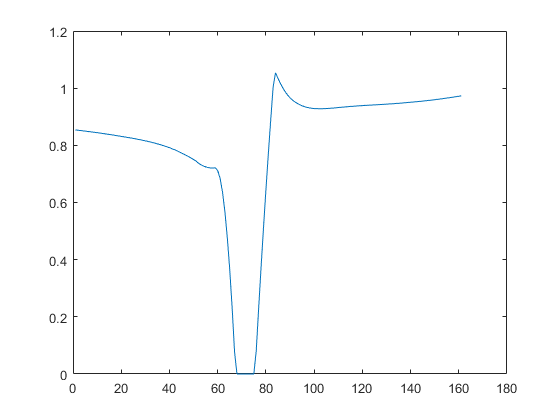

plot(avg_val(x_grid,y_grid))

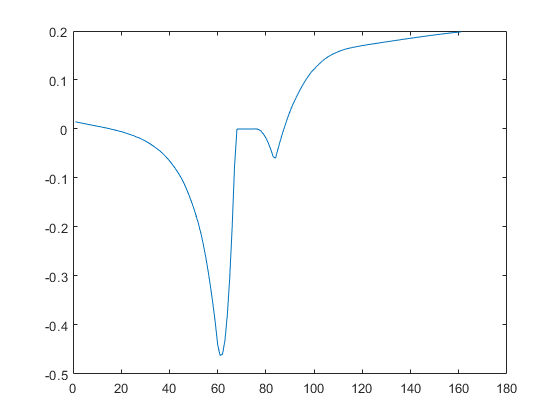

plot(v_inter(x_grid,y_grid))

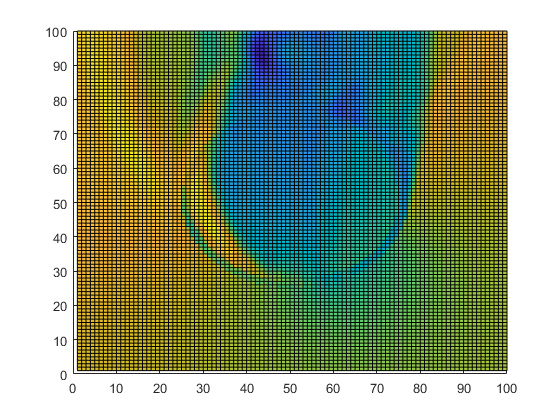

surf(Uavg)
view([0 90])

mean(Uavg(in))

ans = 0.5016

sum(sum(avg_val.Values == 0))

ans = 32

U = flow_data(1).u

U =     1.0025    1.0013    1.0001    0.9988    0.9974    0.9960    0.9945    0.9930    0.9915    0.9899    0.9883    0.9866    0.9849    0.9831    0.9813    0.9794    0.9775    0.9757    0.9740    0.9722    0.9704    0.9686    0.9666    0.9646    0.9627    0.9607    0.9587    0.9569    0.9553    0.9535    0.9516    0.9497    0.9479    0.9463    0.9445    0.9431    0.9414    0.9393    0.9380    0.9368    0.9356    0.9345    0.9331    0.9319    0.9309    0.9298    0.9286    0.9282    0.9275    0.9263
    1.0032    1.0020    1.0008    0.9994    0.9980    0.9965    0.9949    0.9934    0.9919    0.9903    0.9886    0.9868    0.9851    0.9834    0.9815    0.9795    0.9776    0.9757    0.9738    0.9720    0.9702    0.9682    0.9662    0.9641    0.9620    0.9600    0.9580    0.9562    0.9544    0.9525    0.9506    0.9486    0.9467    0.9450    0.9432    0.9417    0.9398    0.9378    0.9366    0.9354    0.9337    0.9326    0.9313    0.9301    0.9289    0.9276    0.9264    0.9259    0.9252    0

syms t
Rx = [1 0 0; 0 cos(t) -sin(t); 0 sin(t) cos(t)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(t\right) & -\sin\left(t\right)\\ 0 & \sin\left(t\right) & \cos\left(t\right) \end{array}\right)$$

Ry = [cos(t) 0 sin(t); 0 1 0; -sin(t) 0 cos(t)]

$$Ry = \left(\begin{array}{ccc} \cos\left(t\right) & 0 & \sin\left(t\right)\\ 0 & 1 & 0\\ -\sin\left(t\right) & 0 & \cos\left(t\right) \end{array}\right)$$

Rz = [cos(t) -sin(t) 0; sin(t) cos(t) 0; 0 0 1]

$$Rz = \left(\begin{array}{ccc} \cos\left(t\right) & -\sin\left(t\right) & 0\\ \sin\left(t\right) & \cos\left(t\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


Rx2 = [cos(t) -sin(t); sin(t) cos(t)]

$$Rx2 = \left(\begin{array}{cc} \cos\left(t\right) & -\sin\left(t\right)\\ \sin\left(t\right) & \cos\left(t\right) \end{array}\right)$$

Rx2*U

Error using  *  (line 334)
Dimensions do not match.